%rnd works like pdf, cdf , inv
%rnd(3) 3x3 matrix or random nrs
%rand uniform distr, randn normal distr

%unifrnd(0,1,1,4) -like rand(1,4)
%unifrnd(-1,1,1,4) -numbers between -1 and 1
%if we just want between 0 and 1 we can use rand

clc;
clear all;

%a) bernoulli distr
s=input("Number of simulations:");
n=input("Number of trials:");
p=-1;
while p<0 | p>1
    p=input("Probability of success:");
end
X=zeros(1,s);
U=rand(n,s);

X=sum(U<p);
U_X=unique(X);
th_X=0:n;
n_X=hist(X,length(U_X));
rel_freq=n_X/s;

%b) binomial distr
binomial_model=[U_X;rel_freq];
disp("Binomial model (nr of successes; relative frequency)");

Binomial model (nr of successes; relative frequency)


disp(binomial_model);

         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000
    0.0012    0.0086    0.0438    0.1211    0.2123    0.2474    0.1959    0.1148    0.0446    0.0094    0.0009



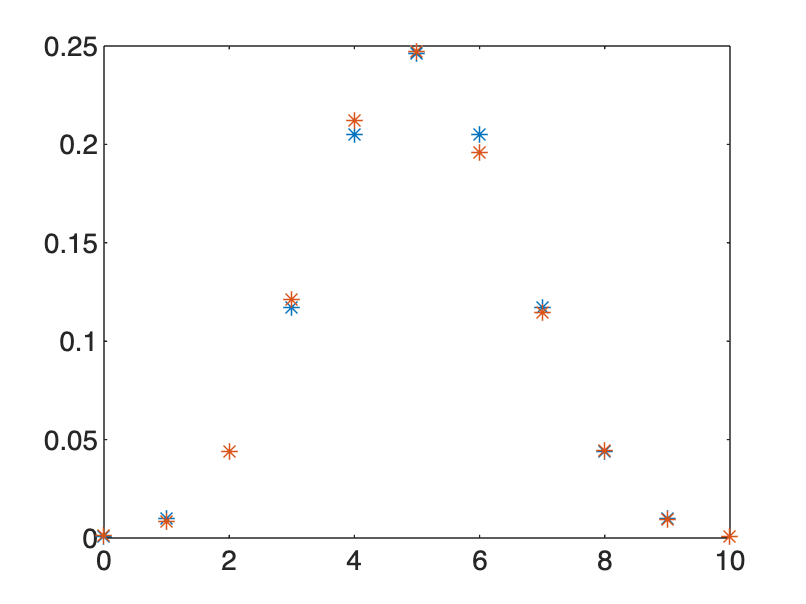


px=binopdf(th_X,n,p);
plot(th_X,px,'*');
hold on
plot(U_X,rel_freq,'*');
hold off

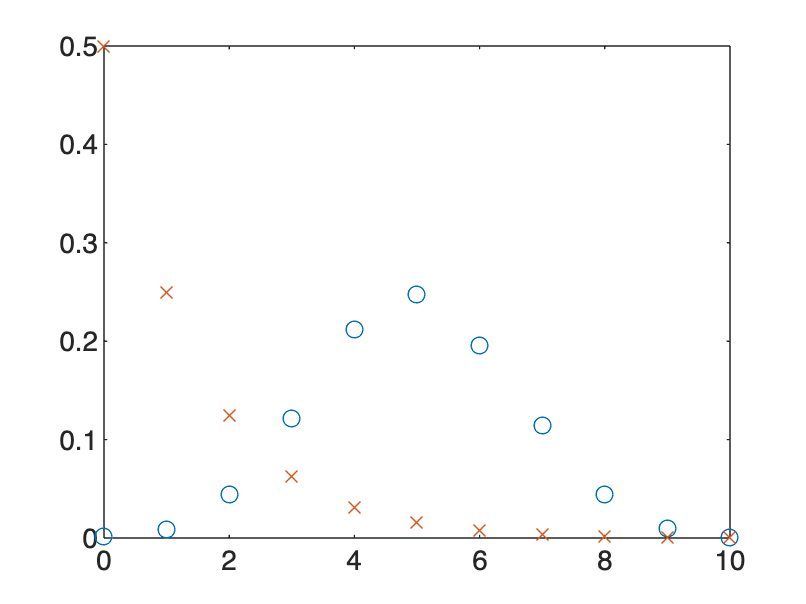


%c) geometric distr
X=zeros(1,s);
for i=1:s
    % the i-th simulation
    while rand>=p
        X(i)=X(i)+1;
    end
end
plot(U_X,rel_freq,'o');
hold on
points=0:max(U_X);
prob=geopdf(points,p);
plot(points,prob,'X');
hold off